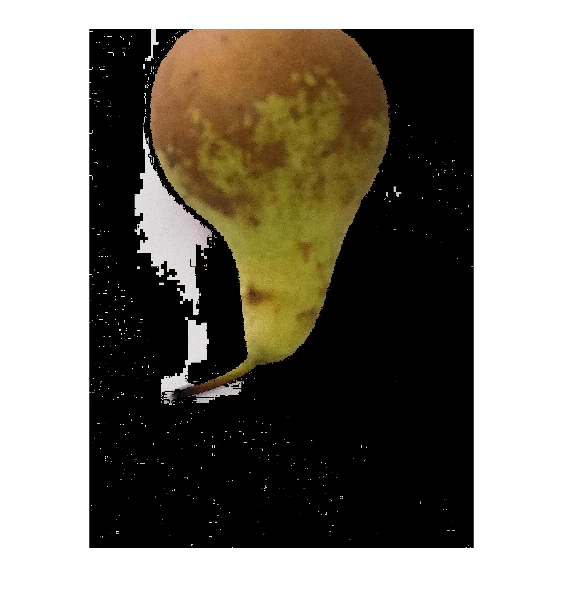

alphabet_vector =     0.6986    0.5889    0.1320
    0.7351    0.2639    0.0978
    0.7645    0.7404    0.7442
    0.8142    0.7143    0.3239
    0.5910    0.4644    0.2344


%First we need to create the alphabet
    alphabet_vector=createalphabet

    match_filename='F02.jpg'

match_filename = 'F02.jpg'

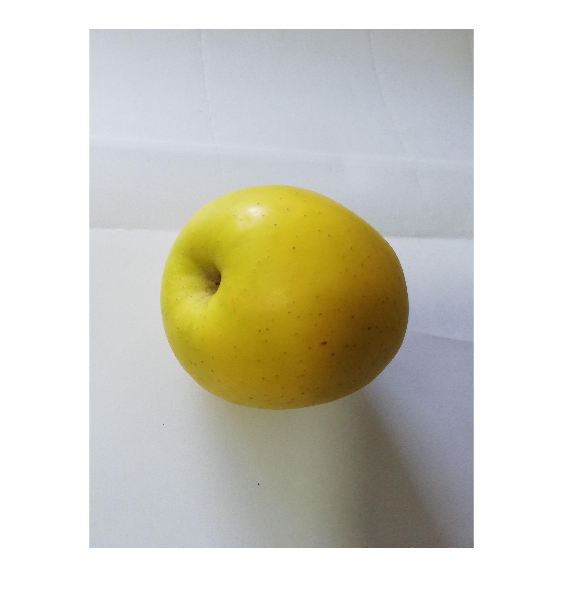

    %%Matching an image%%
    imshow(imread(match_filename))

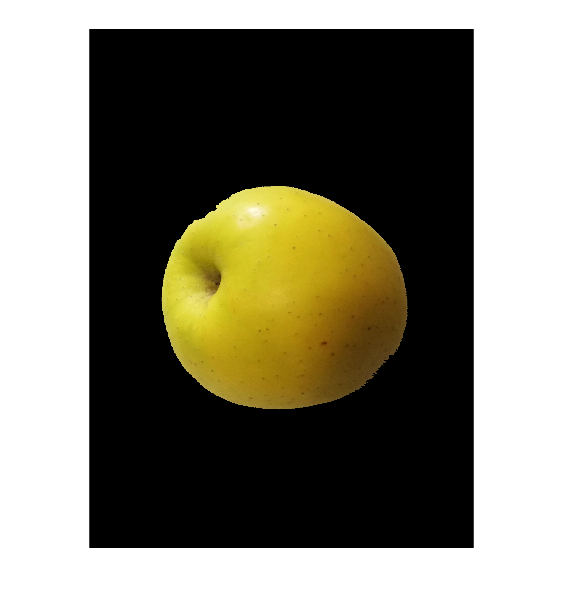

Fruit = "It is an apple"

    Fruit=WhichFruit(match_filename,alphabet_vector)

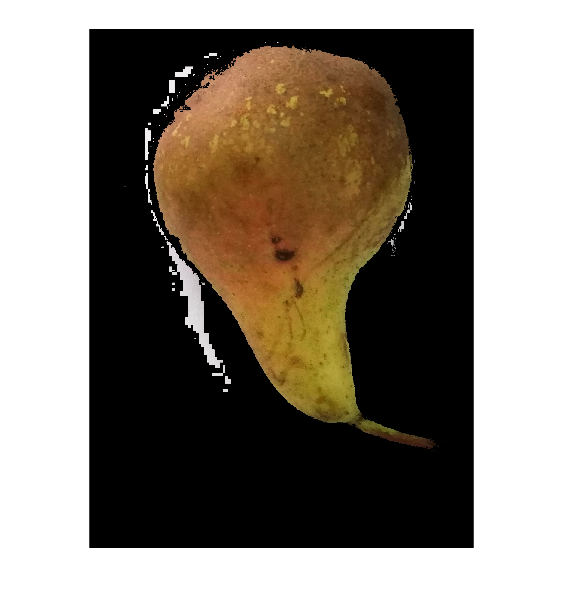

confusionmatrix =      3     0     0     0     0
     0     3     0     0     0
     0     1     2     0     0
     0     0     0     3     0
     0     0     0     0     3


%We create the confusion matrix
confusionmatrix=confmatrix(alphabet_vector)

function WhichFruit = WhichFruit(match_filename,alphabet_vector)
    
    match_vec=RGB_vec(match_filename);
    %imshow(imread(match_filename));
    dist_apple=norm(match_vec-alphabet_vector(1,:));
    dist_tang=norm(match_vec-alphabet_vector(2,:));
    dist_strawberry=norm(match_vec-alphabet_vector(3,:));
    dist_banana=norm(match_vec-alphabet_vector(4,:));
    dist_pear=norm(match_vec-alphabet_vector(5,:));
    dist_vector=[dist_apple dist_tang dist_strawberry dist_banana dist_pear];
    [~,I]=min(dist_vector);
    if(I==1) 
        WhichFruit="It is an apple";
    end
    if(I==2) 
        WhichFruit="It is a tangerine";
    end
    if(I==3) 
        WhichFruit="It is a strawberry";
    end
    if(I==4) 
        WhichFruit="It is a banana";
    end
    if(I==5) 
        WhichFruit="It is a pear";
    end
end


function createalphabet = createalphabet
    vec=zeros(15,3);
    m=0;
    for n=0:4
        for m=1:3
            if(6*n+m)<10
                name="F0"+(6*n+m)+".jpg";
            else
                name="F"+(6*n+m)+".jpg";
            end
            vec((3*n+m),:)=RGB_vec(name);
            %You can put a stop point here to visualize 
            %every image with the mask but you need to uncoment line 211 :
            %imsho(im7)
        end
    end
    
    vecapple=[vec(1,:); vec(2,:);vec(3,:)];
    vecapple=mean(vecapple);
    
    vectang=[vec(4,:); vec(5,:);vec(6,:)];
    vectang=mean(vectang);
    
    vecstrawberry=[vec(7,:); vec(8,:);vec(9,:)];
    vecstrawberry=mean(vecstrawberry);
    
    vecbana=[vec(10,:); vec(11,:);vec(12,:)];
    vecbana=mean(vecbana);
    
    vecpear=[vec(13,:); vec(14,:);vec(15,:)];
    vecpear=mean(vecpear);
    createalphabet=[vecapple;vectang;vecstrawberry;vecbana;vecpear];
end

function confmatrix=confmatrix(alphabet_vector)

    confmatrix=zeros(5,5);
    %%SCANNING IMAGES%%
    
    m=0;h=1;
    for n=1:5
        for m=1:3
            if(3*(2*n-1)+m)<10
                name="F0"+(3*(2*n-1)+m)+".jpg";
            else
                name="F"+(3*(2*n-1)+m)+".jpg";
            end
    
            fruit=WhichFruit(name,alphabet_vector);
            
            if h<=3
                if (strcmp(fruit,"It is an apple"))
                    confmatrix(1,1)=confmatrix(1,1)+1;
                end
                if (strcmp(fruit,"It is a tangerine"))
                    confmatrix(1,2)=confmatrix(1,2)+1;
                end
                if (strcmp(fruit,"It is a strawberry"))
                    confmatrix(1,3)=confmatrix(1,3)+1;
                end
                if (strcmp(fruit,"It is a banana"))
                    confmatrix(1,4)=confmatrix(1,4)+1;
                end
                if (strcmp(fruit,"It is a pear"))
                    confmatrix(1,5)=confmatrix(1,5)+1;                    
                end
            end
            
            if (h>3 && h<=6)
                if (strcmp(fruit,"It is an apple"))
                    confmatrix(2,1)=confmatrix(2,1)+1;
                end
                if (strcmp(fruit,"It is a tangerine"))
                    confmatrix(2,2)=confmatrix(2,2)+1;
                end
                    
                if (strcmp(fruit,"It is a strawberry"))
                    confmatrix(2,3)=confmatrix(2,3)+1;
                end
                if (strcmp(fruit,"It is a banana"))
                    confmatrix(2,4)=confmatrix(2,4)+1;
                end
                if (strcmp(fruit,"It is a pear"))
                    confmatrix(2,5)=confmatrix(2,5)+1;                    
                end
            end

            if (h>6 && h<=9)
                if (strcmp(fruit,"It is an apple"))
                    confmatrix(3,1)=confmatrix(3,1)+1;
                end
                if (strcmp(fruit,"It is a tangerine"))
                    confmatrix(3,2)=confmatrix(3,2)+1;
                end
                if (strcmp(fruit,"It is a strawberry"))
                    confmatrix(3,3)=confmatrix(3,3)+1;
                end
                if (strcmp(fruit,"It is a banana"))
                    confmatrix(3,4)=confmatrix(3,4)+1;
                end
                if (strcmp(fruit,"It is a pear"))
                    confmatrix(3,5)=confmatrix(3,5)+1;                    
                end
            end
            if (h>9 && h<=12)
                if (strcmp(fruit,"It is an apple"))
                    confmatrix(4,1)=confmatrix(4,1)+1;
                end
                if (strcmp(fruit,"It is a tangerine"))
                    confmatrix(4,2)=confmatrix(4,2)+1;
                end
                if (strcmp(fruit,"It is a strawberry"))
                    confmatrix(4,3)=confmatrix(4,3)+1;
                end
                if (strcmp(fruit,"It is a banana"))
                    confmatrix(4,4)=confmatrix(4,4)+1;
                end
                if (strcmp(fruit,"It is a pear"))
                    confmatrix(4,5)=confmatrix(4,5)+1;                    
                end
            end
            if (h>12 && h<=15)
                if (strcmp(fruit,"It is an apple"))
                    confmatrix(5,1)=confmatrix(5,1)+1;
                end
                if (strcmp(fruit,"It is a tangerine"))
                    confmatrix(5,2)=confmatrix(5,2)+1;
                end
                if (strcmp(fruit,"It is a strawberry"))
                    confmatrix(5,3)=confmatrix(5,3)+1;
                end
                if (strcmp(fruit,"It is a banana"))
                    confmatrix(5,4)=confmatrix(5,4)+1;
                end
                if (strcmp(fruit,"It is a pear"))
                    confmatrix(5,5)=confmatrix(5,5)+1;                    
                end
            end
            
            h=h+1;

            %name
            %confmatrix
            
            
        end
    end
    
end
function RGB_vec = RGB_vec(filename)
    im1=imread(filename);
    im2=im2double(im1);
    I=rgb2gray(im2);
    %imshow(im2);
    %imshow(I);
    maximum= max(max(I));
    minimum = min(min(I));
    im3 = (im1-minimum)/(maximum-minimum);
    im3=im2double(im3);
    imshow(im3);
    im4=rgb2hsv(im3);
    im4=rgb2gray(im4);
    imshow(im4);
    threshold=graythresh(im4);
    im5=(im4>threshold);
    im5 = imfill(im5, 'holes');
    imshow(im5);
 
    im7=im3.*im5;
    imshow(im7);
    R=im7(:,:,1);
    r=R(R>0);
    r=r(r<1);
    Rmean=mean(mean(r));
    G=im7(:,:,2);
    g=G(G>0);
    g=g(g<1);
    Gmean=mean(mean(g));
    B=im7(:,:,3);
    b=B(B>0);
    b=b(b<1);
    Bmean=mean(mean(b));
    RGB_vec=[Rmean Gmean Bmean];
end

